# 4.1—4.2 DFT 的效率问题与按时间抽取的 FFT：运算量、实测时间、位反转、蝶形逐级结果

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：运算量——直接计算 N² 次复乘，FFT (N/2)log2N 次（教材式 (4.2.16)、表 4.2.1）

预测：N=2048 时两者差多少倍？

Nlist = 2.^(3:14);
md = Nlist.^2;                                     % 直接计算 DFT 的复乘数
mF = Nlist/2 .* log2(Nlist);                       % 按时间抽取 FFT 的复乘数
ratio = md ./ mF;

## 演示2：实测时间——按定义的矩阵乘法 vs fft

Ntime = 2.^(6:12); tDirect = zeros(size(Ntime)); tFFT = zeros(size(Ntime));
for i = 1:numel(Ntime)
    N = Ntime(i); x = randn(1, N) + 1i*randn(1, N);
    n = 0:N-1; W = exp(-2i*pi*(n'*n)/N);           % N×N 的 W_N^{kn} 矩阵
    reps = max(1, round(2e7/N^2));
    t0 = tic; for r = 1:reps, Xd = W*x.'; end; tDirect(i) = toc(t0)/reps;
    reps = 200;
    t0 = tic; for r = 1:reps, Xf = fft(x); end; tFFT(i) = toc(t0)/reps;
    assert(max(abs(Xd.' - Xf)) < 1e-6*N, '矩阵法与 fft 不一致');
end

## 演示3：自己写一个按时间抽取的基-2 FFT，并与 fft 对照

步骤：位反转重排输入 → v=log2N 级，每级 N/2 个蝶形 → 自然顺序输出

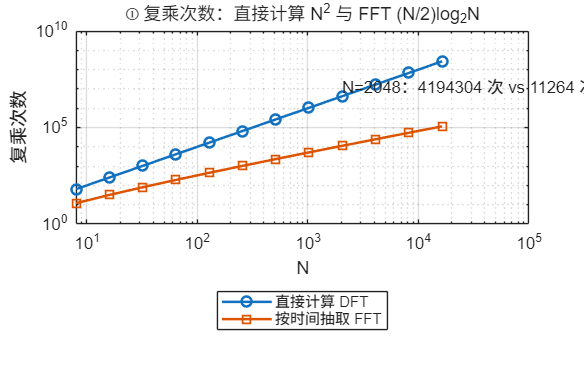

N8 = 8; x8 = (1:8);                                % 教材图 4.2.5 的 N=8 例子
[X8, stages8, order8] = fft_dit(x8);               % stages8 每一行是一级蝶形之后的中间结果
xTest = randn(1, 1024) + 1i*randn(1, 1024);
errDIT = max(abs(fft_dit(xTest) - fft(xTest)));
bitrev = order8 - 1;                               % N=8 的位反转顺序：0 4 2 6 1 5 3 7

if ~LIVE, f1 = figure('Name','01 FFT 运算量与 DIT','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); loglog(Nlist, md, '-o', 'LineWidth', 1.5); hold on; loglog(Nlist, mF, '-s', 'LineWidth', 1.5); grid on;
text(Nlist(end-3), md(end-3)*3, sprintf('N=2048：%d 次 vs %d 次，%.0f 倍', md(9), mF(9), ratio(9)));
title('① 复乘次数：直接计算 N^2 与 FFT (N/2)log_2N'); xlabel('N'); ylabel('复乘次数'); legend('直接计算 DFT','按时间抽取 FFT');

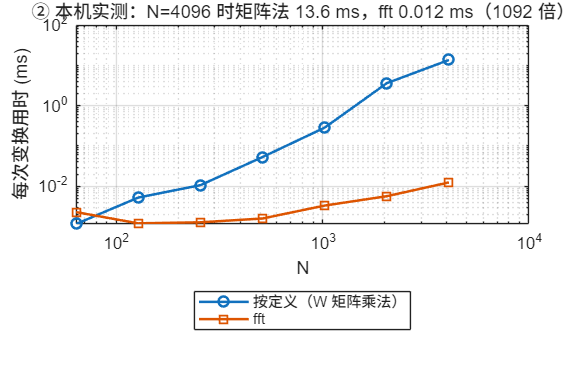

newpanel(); loglog(Ntime, tDirect*1e3, '-o', 'LineWidth', 1.5); hold on; loglog(Ntime, tFFT*1e3, '-s', 'LineWidth', 1.5); grid on;
title(sprintf('② 本机实测：N=%d 时矩阵法 %.1f ms，fft %.3f ms（%.0f 倍）', Ntime(end), tDirect(end)*1e3, tFFT(end)*1e3, tDirect(end)/tFFT(end)));
xlabel('N'); ylabel('每次变换用时 (ms)'); legend('按定义（W 矩阵乘法）','fft');

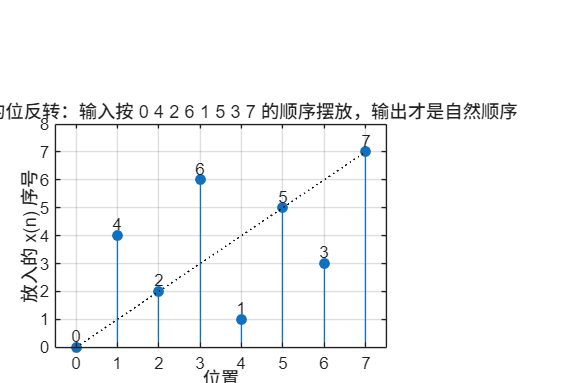

newpanel(); stem(0:7, bitrev, 'filled', 'MarkerSize', 6); hold on; plot(0:7, 0:7, 'k:'); grid on; xlim([-0.5 7.5]); ylim([0 8]);
text(0:7, bitrev + 0.4, string(bitrev), 'HorizontalAlignment', 'center');
title('③ N=8 的位反转：输入按 0 4 2 6 1 5 3 7 的顺序摆放，输出才是自然顺序'); xlabel('位置'); ylabel('放入的 x(n) 序号');

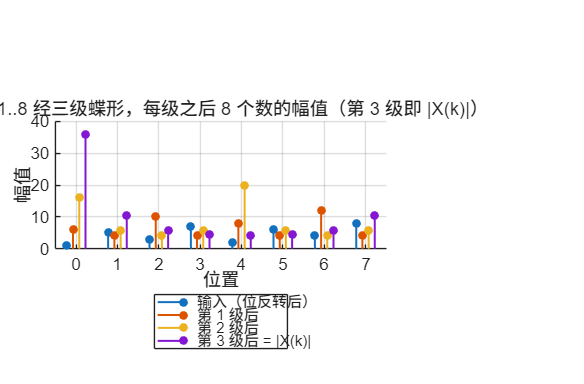

newpanel(); hold on;
for s = 1:size(stages8, 1)
    stem((0:7) + (s-2.5)*0.15, abs(stages8(s, :)), 'filled', 'MarkerSize', 4, 'LineWidth', 1.2);
end
grid on; xlim([-0.5 7.5]);
title('④ x=1..8 经三级蝶形，每级之后 8 个数的幅值（第 3 级即 |X(k)|）'); xlabel('位置'); ylabel('幅值');
legend('输入（位反转后）','第 1 级后','第 2 级后','第 3 级后 = |X(k)|');

if ~LIVE, sgtitle('DFT 太慢 → 分成两半再分 → 位反转 + 蝶形：按时间抽取的 FFT'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '01-fft-cost-dit.png'), 'Resolution', 150); end

## 教师核验

assert(abs(ratio(9) - 2048^2/(1024*11)) < 1e-9, 'N=2048 的比值应为 372.4');
assert(errDIT < 1e-9, '自写 DIT 与 fft 不一致');
assert(isequal(bitrev, [0 4 2 6 1 5 3 7]), '位反转顺序不符');
assert(max(abs(X8 - fft(x8))) < 1e-12, 'N=8 结果不符');
assert(tDirect(end) > tFFT(end), '实测中 fft 应更快');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'N_list', Nlist, 'direct_mults', md, 'fft_mults', mF, 'ratio', ratio, ...
    'timing_N', Ntime, 'direct_seconds', tDirect, 'fft_seconds', tFFT, 'speedup_at_max_N', tDirect(end)/tFFT(end), ...
    'dit_vs_fft_max_err_1024', errDIT, 'bitreversal_N8', bitrev, 'X8_abs', abs(X8), 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-fft-cost.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

             matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                     run_at: '2026-09-18 19:56:10'
                     N_list: [8 16 32 64 128 256 512 1024 2048 4096 8192 16384]
               direct_mults: [64 256 1024 4096 16384 65536 262144 1048576 4194304 16777216 67108864 268435456]
                  fft_mults: [12 32 80 192 448 1024 2304 5120 11264 24576 53248 114688]
                      ratio: [5.3333 8 12.8000 21.3333 36.5714 64 113.7778 204.8000 372.3636 682.6667 1.2603e+03 2.3406e+03]
                   timing_N: [64 128 256 512 1024 2048 4096]
             direct_seconds: [1.1562e-06 5.2280e-06 1.0604e-05 5.2913e-05 2.8376e-04 0.0036 0.0136]
                fft_seconds: [2.2810e-06 1.2015e-06 1.2730e-06 1.5830e-06 3.3145e-06 5.6585e-06 1.2441e-05]
           speedup_at_max_N: 1.0923e+03
    dit_vs_fft_max_err_1024: 6.7032e-14
             bitreversal_N8: [0 4 2 6 1 5 3 7]
                     X8_abs: [36 10.4525 5.6569 4.3296 4 4.3296 5.6569 10.4525]
     


function [X, stages, order] = fft_dit(x)
% 按时间抽取的基-2 FFT（教材 4.2）：位反转重排 + v 级原位蝶形。返回每级之后的中间结果。
x = x(:).'; N = numel(x); v = log2(N); assert(v == round(v), 'N 必须是 2 的幂');
order = bitrevorder_basic(N);                      % 位反转顺序（1 起）
X = x(order); stages = zeros(v + 1, N); stages(1, :) = X;
for s = 1:v                                        % 第 s 级：蝶形跨度 L = 2^s
    L = 2^s; half = L/2; W = exp(-2i*pi*(0:half-1)/L);
    for start = 1:L:N
        for k = 0:half-1
            a = X(start + k); b = W(k+1) * X(start + k + half);   % DIT：先乘旋转因子
            X(start + k) = a + b; X(start + k + half) = a - b;
        end
    end
    stages(s + 1, :) = X;
end
end

function order = bitrevorder_basic(N)
v = log2(N); order = zeros(1, N);
for n = 0:N-1
    r = 0; m = n;
    for b = 1:v, r = r*2 + mod(m, 2); m = floor(m/2); end
    order(n+1) = r + 1;
end
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end